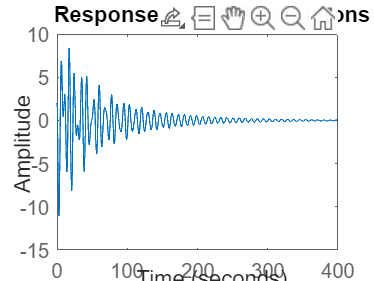

% Initial conditions for the observer
InitialStates = [2, 0, 4, 0, 6, 0, 0, 0, 0, 0, 0, 0];

% Desired eigenvalues for the observer
ObserverEigenvalues = [-2.4, -4.2, -6.8, -8.10, -10, -12];

% Controller Gain using LQR
ControllerGain = lqr(A, B, Q, R);

% Observer Gain for different configurations
GainObserver1 = place(A', C1', ObserverEigenvalues)';
GainObserver3 = place(A', C3', ObserverEigenvalues)';
GainObserver4 = place(A', C4', ObserverEigenvalues)';

% Case 1: Augmented System Matrices
AugmentedA1 = [A-B*ControllerGain, B*ControllerGain; zeros(size(A)), A-GainObserver1*C1];
AugmentedB1 = [B; zeros(size(B))];
AugmentedC1 = [C1, zeros(size(C1))];

% Case 3: Augmented System Matrices
AugmentedA3 = [A-B*ControllerGain, B*ControllerGain; zeros(size(A)), A-GainObserver3*C3];
AugmentedC3 = [C3, zeros(size(C3))];

% Case 4: Augmented System Matrices
AugmentedA4 = [A-B*ControllerGain, B*ControllerGain; zeros(size(A)), A-GainObserver4*C4];
AugmentedC4 = [C4, zeros(size(C4))];

% System Analysis for Case 1
SystemCase1 = ss(AugmentedA1, AugmentedB1, AugmentedC1, D);
figure;
initial(SystemCase1, InitialStates);

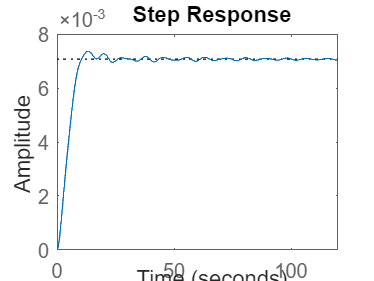

figure;
step(SystemCase1);

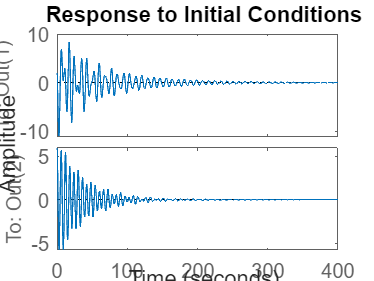


% System Analysis for Case 3
SystemCase3 = ss(AugmentedA3, AugmentedB1, AugmentedC3, D);
figure;
initial(SystemCase3, InitialStates);

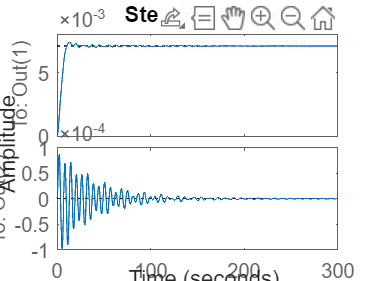

figure;
step(SystemCase3);

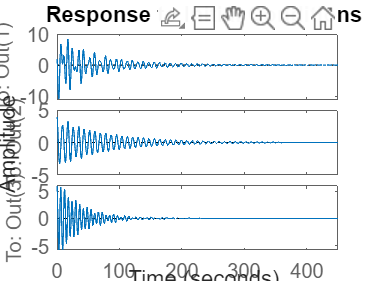


% System Analysis for Case 4
SystemCase4 = ss(AugmentedA4, AugmentedB1, AugmentedC4, D);
figure;
initial(SystemCase4, InitialStates);

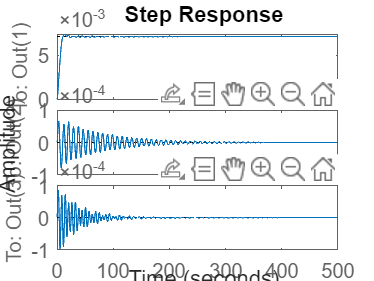

figure;
step(SystemCase4);